# 第2章 离散时间信号和系统分析基础

## 2.9 系统函数

### 2.9.4 系统函数的几何确定法

#### `Ch2_9_1`

`已知系统函数`


$$H\left(z\right)=\frac{\sum_{r=0}^M b_r z^{-r} }{1-\sum_{k=1}^N a_k z^{-k} }=\frac{1+0\ldotp 5z^{-1} }{1-z^{-1} +0\ldotp 5z^{-2} }$$


`求零极点图和幅频``、``相频响应``。`

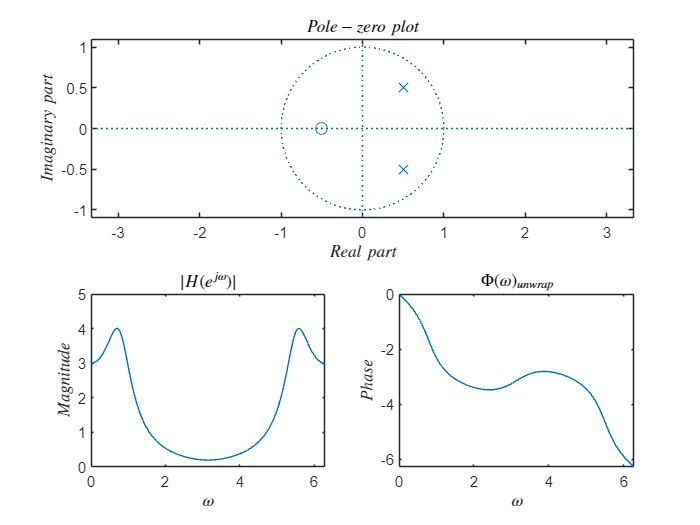

%系统函数
b=[0 1 0.5];
a=[1 -1 0.5];
%零极点图
subplot(2,2,[1, 2]);
zplane(b, a);
title('$Pole-zero\;plot$', 'Interpreter', 'LaTex');
xlabel('$Real\;part$', 'Interpreter', 'LaTex')
ylabel('$Imaginary\;part$', 'Interpreter', 'LaTex');
%幅频响应
[H, w] = freqz(b, a, 1000, 'whole');
subplot(223);
plot(w, abs(H));
axis([0 2*pi 0 5]);
title('$|H(e^{j\omega})|$', 'Interpreter', 'LaTex');
ylabel('$Magnitude$', 'Interpreter', 'LaTex')
xlabel('$\omega$', 'Interpreter', 'LaTex');
subplot(224);
%相频响应
plot(w, unwrap(angle(H)));
title('$\Phi(\omega)_{unwrap}$', 'Interpreter', 'LaTex');
ylabel('$Phase$', 'Interpreter', 'LaTex')
xlabel('$\omega$', 'Interpreter', 'LaTex');